## Eksamen

close all, clear, clc;
% Opgave 1
% A = Have en college-uddannelse
% B = Foretrække vin over øl
P_A = 0.39;
P_notA = 0.61;
P_B_A = 0.72;
P_B_notA = 0.41;

P_B = P_B_A*P_A + P_B_notA*P_notA;
P_A_B = P_B_A*P_A/P_B

P_A_B = 0.5289


% Opgave 2
f0 = -2 * (2+1)/11;
f1 = -1 * (1+1)/11;
f2 = 0 * (0+1)/11;
f3 = 1 * (1+1)/11;
f4 = 2 * (2+1)/11;
mu_x = f0+f1+f2+f3+f4;
v0 = (-2 - mu_x)^2 * (2+1)/11;
v1 = (-1 - mu_x)^2 * (1+1)/11;
v2 = (0 - mu_x)^2 * (0+1)/11;
v3 = (1 - mu_x)^2 * (1+1)/11;
v4 = (2 - mu_x)^2 * (2+1)/11;
sigma_x = v0+v1+v2+v3+v4

sigma_x = 2.5455


% Opgave 3
P_less_11 = binomial_prob(12,0.8,0) + binomial_prob(12,0.8,1) + binomial_prob(12,0.8,2) + binomial_prob(12,0.8,3) + binomial_prob(12,0.8,4) + binomial_prob(12,0.8,5) + binomial_prob(12,0.8,6) + binomial_prob(12,0.8,7) + binomial_prob(12,0.8,8) + binomial_prob(12,0.8,9) + binomial_prob(12,0.8,10)

P_less_11 = 0.7251

%P_less_11 = binocdf(10,12,0.8)

% Opgave 4
mu = -4

mu = -4

sigma = sqrt(4)

sigma = 2

P = 1 - normcdf(0,mu,sigma)

P = 0.0228


% Opgave 5
fun = @(x) 3/2.*x.^3;
mu_x = integral(fun,-1,1);

fun2 = @(x) 3/2.*x.^4;
sigma_x = integral(fun2,-1,1) - mu_x^2

sigma_x = 0.6000


% Opgave 6
P = 1 - chi2cdf(18.31,10)

P = 0.0500


% Opgave 7
syms x
f_X = 3/8 * (1+x^2);
cdf = int(f_X)

$$cdf = \frac{x\,\left(x^{2}+3\right)}{8}$$


% P(-1 <= x <= 1) = 1
%F_b = (1*(1^2+3))/8
%F_a = ((-1)*((-1)^2+3))/8
% P = F_b - F_a % = 1

% Opgave 8
fun = @(x,y) 9/4.*x.^2.*y.^2;
P = integral2(fun,0.5,1,-1,1)

P = 0.4375

% vpa(7/16) = 0.4375

% Opgave 9
syms x y
f_XY = (1/2)^(y+2) * 1/(1-(1/2))

$$f\_XY = 2\,{\left(\frac{1}{2}\right)}^{y+2}$$

$$f\_Y = 2\,{\left(\frac{1}{2}\right)}^{y+2}$$

%f_Y = int(f_XY,x,-1,1)

% Opgave 10
data = [13 8 11 11 10];
sigma_sq = var(data)

sigma_sq = 3.3000


% Opgave 11
dataX = [9 4 6 2];
dataY = [-3 4 0 5];
cov = cov(dataX,dataY)

cov =     8.9167  -10.8333
  -10.8333   13.6667



% Opgave 12
syms x a
f = a^x/factorial(x)*exp(-a);
L = prod(f);
a_hat = solve(diff(log(L),a)==0,a)

$$a\_hat = x$$


% Opgave 13
data = [4 7 5 4 8 7 6];
[H p CI] = ttest(data,4,'Alpha',0.1)

H = 1

p = 0.0205

CI =     4.7014    7.0129



% Opgave 14
n = length(data);
s_sq = var(data);

lo = ((n-1)*s_sq)/(chi2inv(0.05/2,n-1))

lo = 12.0073

hi = ((n-1)*s_sq)/(chi2inv(1-0.05/2,n-1))

hi = 1.0282


% Opgave 15
mu_hat = mean(data)

mu_hat = 5.8571

mu_0 = 7;
s = std(data);

t0 = (mu_hat-mu_0)/(s/sqrt(n))

t0 = -1.9215


% Opgave 16
p = 2 * (1 - tcdf(abs(t0),n-1))

p = 0.1030


% Opgave 17
sigma_0_sq = 2;
chi_sq_0 = ((n-1)*s_sq)/sigma_0_sq

chi_sq_0 = 7.4286

p = 2 * (1 - chi2cdf(abs(chi_sq_0),n-1))

p = 0.5660


% Opgave 18
dataX = [13 16 9 11 14];
dataY = [25 32 28 24 31 30];
n1 = length(dataX);
n2 = length(dataY);
s1_sq = var(dataX);
s2_sq = var(dataY);

sp_sq = ((n1-1)*s1_sq+(n2-1)*s2_sq)/(n1+n2-2)

sp_sq = 9.1704


% Opgave 19
dataX = [15 10 13 16 14];
dataY = [11 9 11 12 10];

[H p CI] = ttest(dataX,dataY+1)

H = 1

p = 0.0341

CI =     0.2440    3.7560



% Tjek
%n = length(dataX);
%Dj = dataX-dataY;
%D_bar = mean(Dj);
%s_D = std(Dj);
%t0 = (D_bar - 1)/(s_D/sqrt(n))
%p = 2 * (1 - tcdf(t0,n-1))

% Opgave 20
dataX = [-3 -2 -1 -1 0 1 1 3]';
dataY = [0 -1 0 1 0 1 2 2]';
Reg_X = [dataX ones(size(dataX))];

[b, ~, ~, ~, STATS] = regress(dataY,Reg_X)

b =     0.4412
    0.7353


STATS =     0.6303   10.2273    0.0186    0.4853


Beta_1 = b(1)

Beta_1 = 0.4412

Alpha = b(2)

Alpha = 0.7353


% Tjek tjek
%x_bar = mean(dataX);
%y_bar = mean(dataY);
%b_0_qmark = y_bar - b(1)*x_bar;

% Opgave 21
R_2 = STATS(1)

R_2 = 0.6303


% Opgave 22
sigma_sq = STATS(4);
s_XX = sum((dataX - mean(dataX)).^2);
alpha = 0.05;
n = length(dataX);

B1_hi = Beta_1 + sqrt(sigma_sq/s_XX) * tinv(1-alpha/2,n-2)

B1_hi = 0.7787

B1_lo = Beta_1 - sqrt(sigma_sq/s_XX) * tinv(1-alpha/2,n-2)

B1_lo = 0.1036

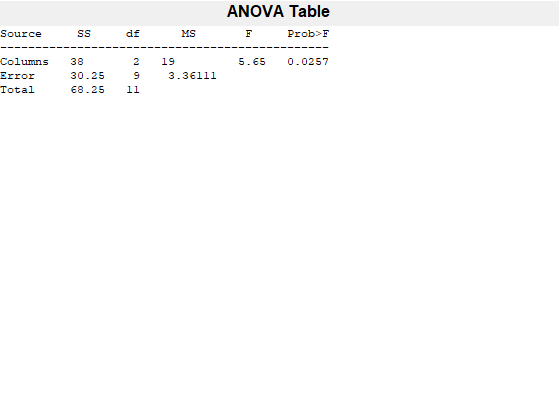

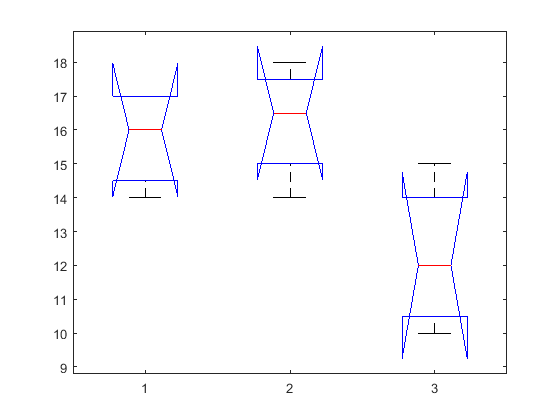


% Opgave 23
dataX = [15 17 14 17]';
dataY = [16 18 17 14]';
dataZ = [15 11 10 13]';
y = [dataX dataY dataZ];

[p,TBL,STATS] = anova1(y);

f0 = TBL{2,5}

f0 = 5.6529


% Opgave 24
% sigma_sq_hat = S_W_sq
sigma_sq = TBL{3,4}

sigma_sq = 3.3611

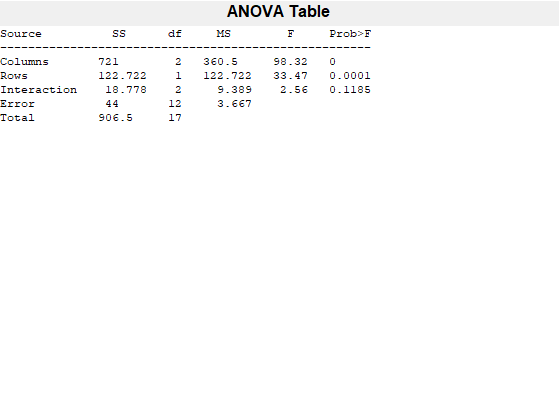

p =     0.0000    0.0001    0.1185



% Opgave 25
data = [12 6 17
        10 7 17
        15 4 22
        18 10 25
        17 8 26
        18 7 28];
p = anova2(data,3)